# 简化模型动力学分析

## 1 轮腿机器人模型

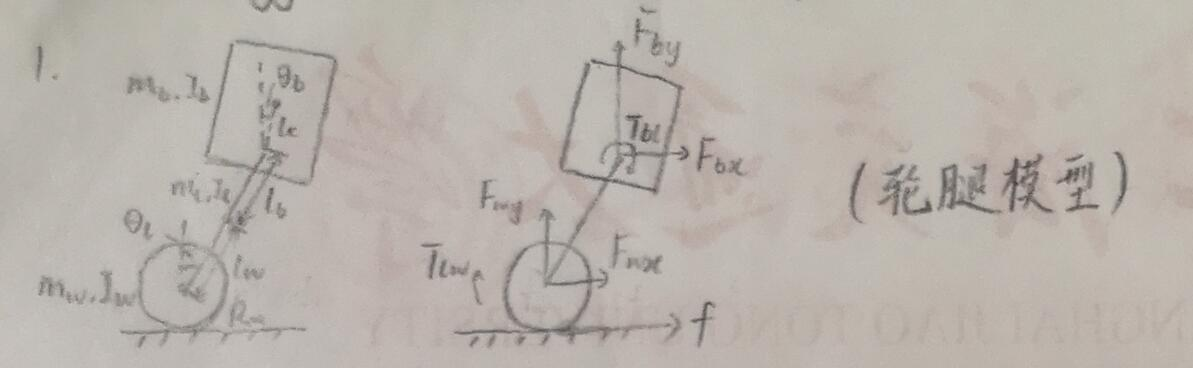

$m_w$: 驱动轮质量

$I_w$: 驱动轮惯量

$m_l$: 腿质量

$I_l$: 腿惯量

$m_b$: 机体质量

$I_b$: 机体惯量

$R_w$: 轮半径

$l_w$: 腿质心到轮轴距离

$l_b$: 腿质心到机体-腿轴（虚拟）距离

$l_c$: 机体-腿轴（虚拟）到机体质心距离

$x_w$: 轮位移

$\theta_l$: 腿倾斜角

$\theta_b$: 机体倾斜角

$T_{lw}$: 腿对驱动轮转矩

$T_{bl}$: 机体对腿转矩

% gravitational acceleration
syms g
% robot parameters
syms m_w I_w m_l I_l m_b I_b
syms R_w l_w l_b l_c
% state variables
syms x_w x_w_D1 x_w_D2
syms theta_l theta_l_D1 theta_l_D2
syms theta_b theta_b_D1 theta_b_D2
% control variables
syms T_lw T_bl

## 2 动力学方程组

对于轮

  $m_w\ddot{x}_w=f-F_{wx}$    (1)

  $I_w\frac{\ddot{x}_w}{R_w}=T_{lw}-fR_w$    (2)

对于腿

  $m_l\frac{\partial^2}{\partial t^2}(x_w+l_wsin\theta_l)=F_{wx}-F_{bx}$    (3)

  $m_l\frac{\partial^2}{\partial t^2}(l_wcos\theta_l)=F_{wy}-F_{by}-m_lg$    (4)

  $I_l\ddot\theta_l=(F_{wy}l_w+F_{by}l_b)sin\theta_l-(F_{wx}l_w+F_{bx}l_b)cos\theta_l-T_{lw}+T_{bl}$    (5)

对于机体

  $m_b\frac{\partial^2}{\partial t^2}\left(x_w+(l_w+l_b)sin\theta_l+l_csin\theta_b\right)=F_{bx}$    (6)

  $m_b\frac{\partial^2}{\partial t^2}\left((l_w+l_b)cos\theta_l+l_ccos\theta_b\right)=F_{by}-m_bg$    (7)

  $I_b\ddot\theta_b=-T_{bl}-F_{bx}l_ccos\theta_b+F_{by}l_csin\theta_b$    (8)

## 3 方程组求解

联立(1)(2) 得到

  $(I_w+m_wR_w^2)\ddot{x}_w=\frac{T_{lw}}{R_w}-F_{wx}$    (9)

根据(3)(4)(6)(7)得到内部力$F_{wx}, F_{wy}, F_{bx}, F_{by}$的表达式

  $F_{bx}=m_b\left(\ddot x_w+(l_w+l_b)(cos\theta_l\ddot\theta_l-sin\theta_l\dot\theta_l^2)+l_c(cos\theta_b\ddot\theta_b-sin\theta_b\dot\theta_b^2)\right)$    (10)

  $F_{by}=m_b\left(g-(l_w+l_b)(sin\theta_l\ddot\theta_l+cos\theta_l\dot\theta_l^2)-l_c(sin\theta_b\ddot\theta_b+cos\theta_b\dot\theta_b^2)\right)$    (11)

  $F_{wx}=m_l\left(\ddot x_w+l_w(cos\theta_l\ddot\theta_l-sin\theta_l\dot\theta_l^2)\right)+F_{bx}$    (12)

  $F_{wy}=m_l\left(g-l_w(sin\theta_l\ddot\theta_l+cos\theta_l\dot\theta_l^2)\right)+F_{by}$    (13)

将(10)~(13)代入后求解式(5)(8)(9)可得到$\ddot x_w, \ddot\theta_l, \ddot\theta_b$的表达式

% internal forces
F_bx = m_b*(x_w_D2 ...
           +(l_w+l_b)*(cos(theta_l)*theta_l_D2-sin(theta_l)*theta_l_D1^2) ...
           +l_c*(cos(theta_b)*theta_b_D2-sin(theta_b)*theta_b_D1^2));
F_by = m_b*(g ...
           -(l_w+l_b)*(sin(theta_l)*theta_l_D2+cos(theta_l)*theta_l_D1^2) ...
           -l_c*(sin(theta_b)*theta_b_D2+cos(theta_b)*theta_b_D1^2));
F_wx = m_l*(x_w_D2 ...
           +l_w*(cos(theta_l)*theta_l_D2-sin(theta_l)*theta_l_D1^2));
F_wy = m_l*(g ...
           -l_w*(sin(theta_l)*theta_l_D2+cos(theta_l)*theta_l_D1^2));
% solve equation
eq1 = (F_wy*l_w+F_by*l_b)*sin(theta_l)-(F_wx*l_w+F_bx*l_b)*cos(theta_b) ...
      -T_lw+T_bl-I_l*theta_l_D2;
eq2 = -T_bl-F_bx*l_c*cos(theta_b)+F_by*l_c*sin(theta_b)-I_b*theta_b_D2;
eq3 = T_lw/R_w-F_wx-(m_w+I_w/R_w^2)*x_w_D2;
[x_w_D2_sol,theta_l_D2_sol,theta_b_D2_sol] = ...
    solve(eq1,eq2,eq3,x_w_D2,theta_l_D2,theta_b_D2);

## 4 状态空间模型

状态向量 $\mathbf{x}=
\left[
\matrix{x_w & \dot x_w & \theta_l & \dot\theta_l & \theta_b & \dot\theta_b}
\right]^T$

控制向量 $\mathbf{u}=
\left[
\matrix{T_{lw} & T_{bl}}
\right]^T$

输出向量 $\mathbf{y}=\mathbf{x}$

状态空间方程（非线性）

$\mathbf{\dot x}=f(\mathbf{x},\mathbf{u})$    (14)

在平衡位置 $\bar\mathbf{x}$ 附近线性化得到状态方程

$\mathbf{\dot x}=A\mathbf{x}+B\mathbf{u}$    (15)

其中

$A=\frac{\partial f}{\partial \mathbf{x}}(\bar\mathbf{x},\mathbf{u})=
\left[
\matrix{
0 & 1 & 0 & 0 & 0 & 0 \cr
0 & 0 & a_1 & 0 & a_2 & 0 \cr
0 & 0 & 0 & 1 & 0 & 0 \cr
0 & 0 & a_3 & 0 & a_4 & 0 \cr
0 & 0 & 0 & 0 & 0 & 1 \cr
0 & 0 & a_5 & 0 & a_6 & 0 \cr
}
\right]$    (16)

$B=\frac{\partial f}{\partial \mathbf{u}}(\bar\mathbf{x},\mathbf{u})=
\left[
\matrix{
0 & 0 \cr
b_1 & b_2 \cr
0 & 0 \cr
b_3 & b_4 \cr
0 & 0 \cr
b_5 & b_6 \cr
}
\right]$    (17)

% state space equation
a1 = simplify(subs(diff(x_w_D2_sol,theta_l), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
a2 = simplify(subs(diff(x_w_D2_sol,theta_b), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
a3 = simplify(subs(diff(theta_l_D2_sol,theta_l), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
a4 = simplify(subs(diff(theta_l_D2_sol,theta_b), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
a5 = simplify(subs(diff(theta_b_D2_sol,theta_l), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
a6 = simplify(subs(diff(theta_b_D2_sol,theta_b), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
b1 = simplify(subs(diff(x_w_D2_sol,T_lw), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
b2 = simplify(subs(diff(x_w_D2_sol,T_bl), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
b3 = simplify(subs(diff(theta_l_D2_sol,T_lw), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
b4 = simplify(subs(diff(theta_l_D2_sol,T_bl), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
b5 = simplify(subs(diff(theta_b_D2_sol,T_lw), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
b6 = simplify(subs(diff(theta_b_D2_sol,T_bl), ...
              {theta_l,theta_l_D1,theta_b,theta_b_D1},{0,0,0,0}));
% matrix A, B
A_sym = [
  0,1,0,0,0,0
  0,0,a1,0,a2,0
  0,0,0,1,0,0
  0,0,a3,0,a4,0
  0,0,0,0,0,1
  0,0,a5,0,a6,0];
B_sym = [
  0,0
  b1,b2
  0,0
  b3,b4
  0,0
  b5,b6];

*线性化结果

记


$$\sigma=
\frac{1}
{I_{b}\,I_{l}\,I_{w}+I_{b}\,I_{l}\,{R_{w}}^2\,m_{l}+I_{b}\,I_{l}\,{R_{w}}^2\,m_{w}+I_{b}\,I_{w}\,{l_{b}}^2\,m_{b}+I_{l}\,I_{w}\,{l_{c}}^2\,m_{b}+I_{b}\,I_{w}\,{l_{w}}^2\,m_{l}+I_{b}\,{R_{w}}^2\,{l_{b}}^2\,m_{b}\,m_{l}+I_{b}\,{R_{w}}^2\,{l_{b}}^2\,m_{b}\,m_{w}+I_{l}\,{R_{w}}^2\,{l_{c}}^2\,m_{b}\,m_{l}+I_{l}\,{R_{w}}^2\,{l_{c}}^2\,m_{b}\,m_{w}+I_{b}\,{R_{w}}^2\,{l_{w}}^2\,m_{l}\,m_{w}+I_{w}\,{l_{c}}^2\,{l_{w}}^2\,m_{b}\,m_{l}+I_{b}\,I_{w}\,l_{b}\,l_{w}\,m_{b}+I_{b}\,{R_{w}}^2\,l_{b}\,l_{w}\,m_{b}\,m_{w}+{R_{w}}^2\,{l_{c}}^2\,{l_{w}}^2\,m_{b}\,m_{l}\,m_{w}}$$


在平衡点附近线性化后状态空间方程各系数表达式如下


$$a_1=
-\sigma{{R_{w}}^2\,g\,l_{w}\,m_{l}\,\left(m_{b}\,{l_{c}}^2+I_{b}\right)\,\left(l_{b}\,m_{b}+l_{w}\,m_{l}\right)}$$



$$a_2=
\sigma{{R_{w}}^2\,g\,l_{b}\,{l_{c}}^2\,l_{w}\,{m_{b}}^2\,m_{l}}$$



$$a_3=
\sigma{g\,\left(m_{b}\,{l_{c}}^2+I_{b}\right)\,\left(l_{b}\,m_{b}+l_{w}\,m_{l}\right)\,\left(I_{w}+{R_{w}}^2\,m_{l}+{R_{w}}^2\,m_{w}\right)}$$



$$a_4=
-\sigma{g\,l_{b}\,{l_{c}}^2\,{m_{b}}^2\,\left(I_{w}+{R_{w}}^2\,m_{l}+{R_{w}}^2\,m_{w}\right)}$$



$$a_5=
-\sigma{g\,l_{c}\,m_{b}\,\left(l_{b}\,m_{b}+l_{w}\,m_{l}\right)\,\left(I_{w}\,l_{b}+I_{w}\,l_{w}+{R_{w}}^2\,l_{b}\,m_{l}+{R_{w}}^2\,l_{b}\,m_{w}+{R_{w}}^2\,l_{w}\,m_{w}\right)}$$



$$a_6=
\sigma{g\,l_{c}\,m_{b}\,\left(I_{l}\,I_{w}+I_{l}\,{R_{w}}^2\,m_{l}+I_{l}\,{R_{w}}^2\,m_{w}+I_{w}\,{l_{b}}^2\,m_{b}+I_{w}\,{l_{w}}^2\,m_{l}+{R_{w}}^2\,{l_{b}}^2\,m_{b}\,m_{l}+{R_{w}}^2\,{l_{b}}^2\,m_{b}\,m_{w}+{R_{w}}^2\,{l_{w}}^2\,m_{l}\,m_{w}+I_{w}\,l_{b}\,l_{w}\,m_{b}+{R_{w}}^2\,l_{b}\,l_{w}\,m_{b}\,m_{w}\right)}$$



$$b_1=
\sigma{R_{w}\,\left(I_{b}\,m_{b}\,{l_{b}}^2+I_{b}\,m_{b}\,l_{b}\,l_{w}+m_{b}\,m_{l}\,{l_{c}}^2\,{l_{w}}^2+R_{w}\,m_{b}\,m_{l}\,{l_{c}}^2\,l_{w}+I_{l}\,m_{b}\,{l_{c}}^2+I_{b}\,m_{l}\,{l_{w}}^2+I_{b}\,R_{w}\,m_{l}\,l_{w}+I_{b}\,I_{l}\right)}$$



$$b_2=
-\sigma{{R_{w}}^2\,l_{w}\,m_{l}\,\left(m_{b}\,{l_{c}}^2+l_{b}\,m_{b}\,l_{c}+I_{b}\right)}$$



$$b_3=
-\sigma\left(
{I_{b}\,I_{w}+I_{b}\,{R_{w}}^2\,m_{l}+I_{b}\,{R_{w}}^2\,m_{w}+I_{w}\,{l_{c}}^2\,m_{b}+{R_{w}}^2\,{l_{c}}^2\,m_{b}\,m_{l}+{R_{w}}^2\,{l_{c}}^2\,m_{b}\,m_{w}+I_{b}\,R_{w}\,l_{b}\,m_{b}+I_{b}\,R_{w}\,l_{w}\,m_{l}+R_{w}\,{l_{c}}^2\,l_{w}\,m_{b}\,m_{l}}
\right)$$



$$b_4=
\sigma
{\left(I_{w}+{R_{w}}^2\,m_{l}+{R_{w}}^2\,m_{w}\right)\,\left(m_{b}\,{l_{c}}^2+l_{b}\,m_{b}\,l_{c}+I_{b}\right)}$$



$$b_5=
\sigma{l_{c}\,m_{b}\,\left(I_{w}\,l_{b}+I_{w}\,l_{w}-I_{l}\,R_{w}+{R_{w}}^2\,l_{b}\,m_{l}+{R_{w}}^2\,l_{b}\,m_{w}+{R_{w}}^2\,l_{w}\,m_{w}+R_{w}\,l_{b}\,l_{w}\,m_{l}\right)}$$



$$b_6=
-\sigma\left(
{I_{l}\,I_{w}+I_{l}\,{R_{w}}^2\,m_{l}+I_{l}\,{R_{w}}^2\,m_{w}+I_{w}\,{l_{b}}^2\,m_{b}+I_{w}\,{l_{w}}^2\,m_{l}+{R_{w}}^2\,{l_{b}}^2\,m_{b}\,m_{l}+{R_{w}}^2\,{l_{b}}^2\,m_{b}\,m_{w}+{R_{w}}^2\,{l_{w}}^2\,m_{l}\,m_{w}+I_{w}\,l_{b}\,l_{c}\,m_{b}+I_{w}\,l_{b}\,l_{w}\,m_{b}+I_{w}\,l_{c}\,l_{w}\,m_{b}+{R_{w}}^2\,l_{b}\,l_{c}\,m_{b}\,m_{l}+{R_{w}}^2\,l_{b}\,l_{c}\,m_{b}\,m_{w}+{R_{w}}^2\,l_{b}\,l_{w}\,m_{b}\,m_{w}+{R_{w}}^2\,l_{c}\,l_{w}\,m_{b}\,m_{w}}
\right)$$
